## Tarea 5 

Estudie los ejercicios de la sección 11.5 del capítulo 11, con una breve explicación de los pasos de cada ejemplo.

### 11.5 Spatial Operations

El objetivo de este capitulo es enseñar como plicar diferentes operaciones espaciales a una imágen de un artista muy famoso titulada "la monalisa" proveniente de los ejemplos del libro. Se espera utilizar diferentes metodos computacionales para dada una imagen de entrada, procesarla o interpretarla, generar una producto de salida y analizar las caraterísticas resultantes. 

### 11.5.1 Linear Spatial Filtering

%Y = imfilter(X,K,"conv");

%Imágen cargada y detalles.
mona = rgb2gray(imread("monalisa.png"));
mona

mona = 700×677 uint8 matrix
    53    82   101    62    81   102    89    69    88    74    88    91   119   120    98   114    90   117    79   103    72   106   143   107    71   125   104   118   125   132   114   112   110   119   122    72    96    83   118   113   111   101   113   103   107   104   125   106    81   102
    58    87    95    42    82   103    99    67   106    82    77    84   113   102   109   124    89    95    94   137   109    88   139    90    82   102   100   151   134   134   145   113   106   136   150    75   111   105   137   106   118    88   124   123   120    96   116    86    78    92
    68    86    83    52    90    95    87    70   107    93    81    85   108    91   115   117   101    72   113   131   117    62   123    86    84    90    87   149   113   139   122    89   115   111   120    57    96   106   113   115   117    83   134   123   118    98   121    79   107   102
    67    86    80    76    91    87    72    66    81    96    96   

#### 11.5.1.1 Image Smoothing

Este es un ejemplo de suavisado de imágen de la monalisa. 

Mediante este método, se realiza un cálculo con este kernel para obtener como   resultado de convolucionar una imagen  donde cada píxel de salida es la media de los píxeles en un vecindario 21x21 antes mencionados. 

Este valor resultado medio, provoca que la salida se vea desenfocada-suavizada de la imágen.  

Se utiliza  la función `imfilter para `realizar la convolución de una imagen "mona" con el kernel `K. `

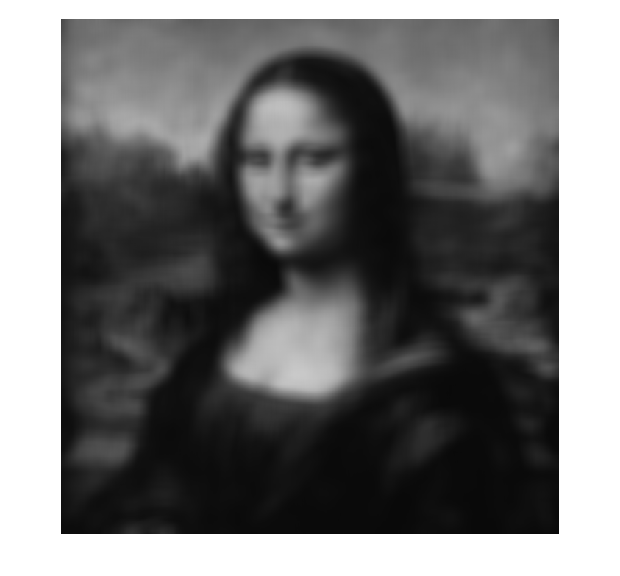

% Matriz cuadrada de convolución 21x21 y sus valores suman = 1
% K es el kernel 
K = ones(21,21) / 21^2;
imshow(imfilter(mona,K,"conv","replicate"));

Ahora, se presenta otra manera de procesar la imágen utilizando la función gaussiana ó filtro difuso. Esta funcion realiza el cálculo de la dispersión de la función gaussiana está controlada por la desviación estándar de la imágen entrante.  En este se utiliza una matriz de 31x31  utilizada para el kernel K y como el parámetro de la desviación estandar de 5 pixels. 

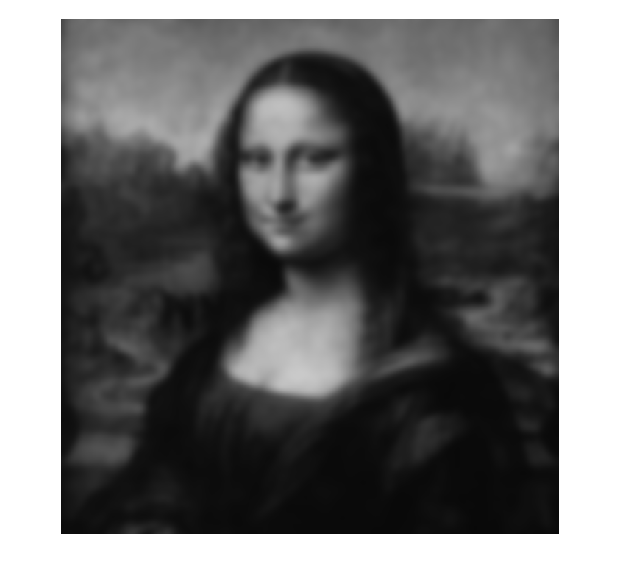

K = fspecial("gaussian",31,5);
imshow(imfilter(mona,K,"replicate"));

Se puede utilizar esta otra función para suavizar, de manera que de una manera conveniente y rápida es utilizando la función altamente optimizada imgaussfilt que usa un filtro Gaussiano con un grado de desviación estándar de 5.

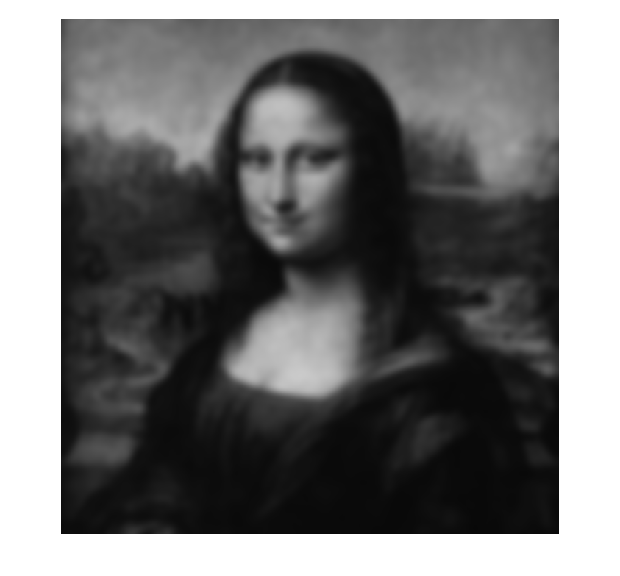

imshow(imgaussfilt(mona,5))

Esta función  se utiliza el filtro K del Kernel antes creado con un nivel de ampliación de un 800% y para [ ] verificar el escalado automático a presentar estirar el contraste” de K. Utilizando el filtro de esta manera se puede ver en dos dimenciones transformando el núcleo de la vista gaussiana mostrada como imagen de intensidad. 

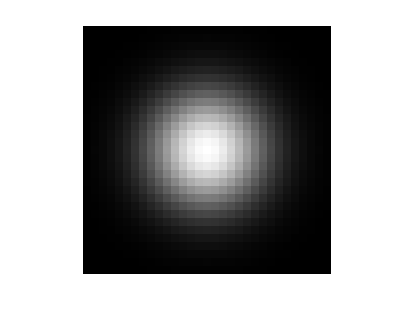

imshow(K,[],InitialMagnification=800);

Utilizando el grafico presentado acontinuación con el Kernel, se presenta el núcleo de sombrero de copa Gaussiana presentando la amplitud en este. 

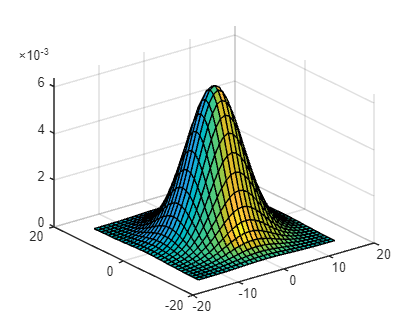

surfl(-15:15,-15:15,K);

Ahora se va a actualizar el valor del Kernel donde utilizando una función especial para representar un disco y en este cao de 8 pixeles.

K = fspecial("disk",8);

Representación similar. 

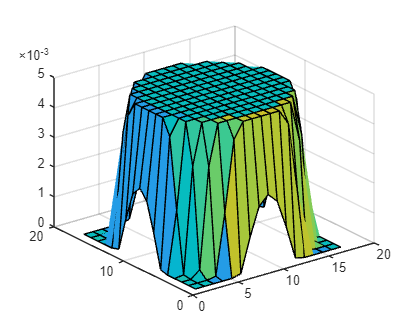

surfl(K);

#### 11.5.1.3 Edge Detection

Se va a cargar la imágen del letrero del Castillo.

Posteriormente se grafica el vector de  los datos de una ** UNA  fila**  del perfil horizontal de la imagen en 360. 

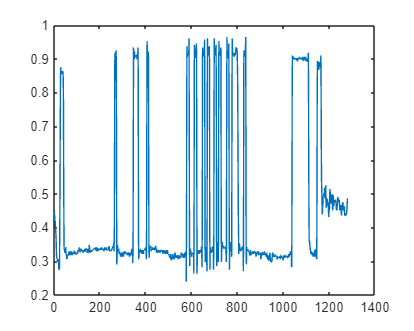

castle = im2double(imread("castle.png"));

p = castle(360,:);

plot(p);

Se calcula las diferencias de inteccidad de dicha fila de la imágen. 

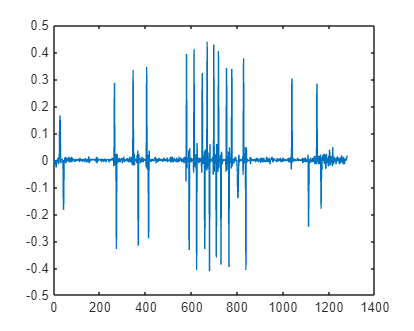

plot(diff(p))

Se crea una matriz de kernel nueva aplicar la convolución con la imágen del rotulo del castillo. donde al realizar esto, se produce un resultado conde se marcan los diferentes borden y gradientes de la imágen. Con el parámetro de se [ ] muestra el valor mínimo, el más negativo, como negro y el valor máximo, el más positivo, como blanco

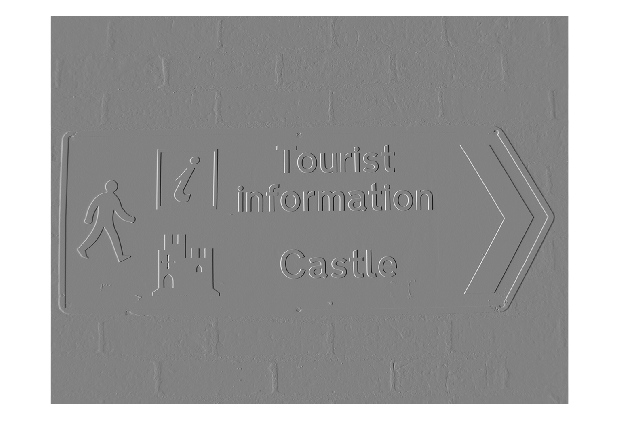

K = [0.5 0 -0.5];
imshow(imfilter(castle,K,"conv"),[]);

El filtro** Sobel, **detecta los cambios en dirección horizontal y vertical en la imágen donde el resultado final convolucionado la suma ponderada del gradiente vertical de la columna actual y las columnas de la izquierda y la derecha

Dv = fspecial("sobel")

Dv =      1     2     1
     0     0     0
    -1    -2    -1


Y este se muestra de ka siguiente manera con la gradiente vertical:

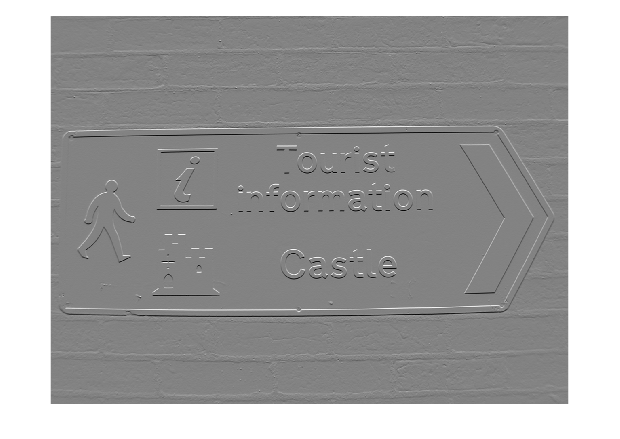

imshow(imfilter(castle,Dv,"conv"),[])

Y este se muestra de ka siguiente manera con la gradiente horizontal:

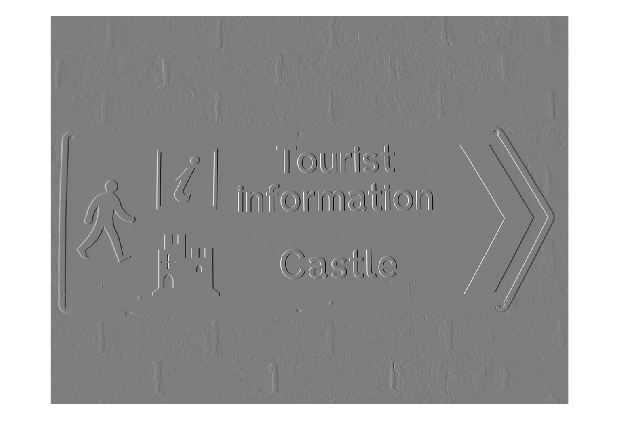

imshow(imfilter(castle,Dv',"conv"),[])

% Not runnable.
%Xv = imfilter(Dv,fspecial("gaussian",hsize,sigma), ...
%              "conv","full");


En esta seccción, con el filtrado derivado de Gaussianas se puede realizar un suavizado selectivo de de una imágen utilizando la imfilter con los parámetros y el filtro fspecial. Gracias  esto se  para detectar bordes y calcular el gradiente de la imagen en cada punto de dirección del gradiente de ima imágen del castillo. El resultaddo es una representación de lo cual proporciona información sobre la dirección de la gradiente y magnitud de la gradiente de los cambios de intensidad. Como se presenta en el grafico mediante la funcion de quiver para dibujar los vectores. 

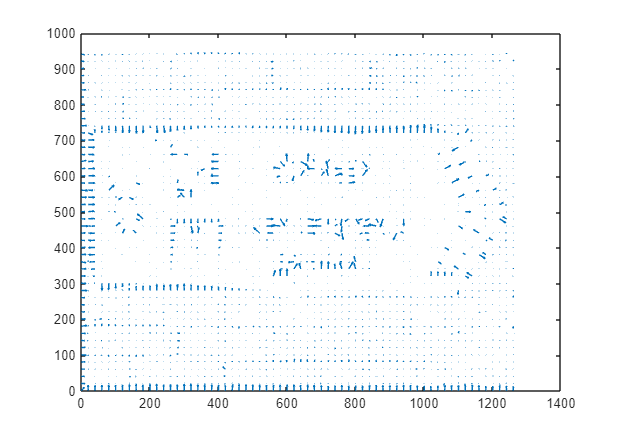

derOfGKernel = imfilter(Dv,fspecial("gaussian",5,2), ...
  "conv","full");
Xv = imfilter(castle,derOfGKernel,"conv");
Xu = imfilter(castle,derOfGKernel',"conv");

m = sqrt(Xu.^2 + Xv.^2);

th = atan2(Xv,Xu);

quiver(1:20:size(th,2), 1:20:size(th,1), ...
  Xu(1:20:end,1:20:end), Xv(1:20:end,1:20:end))

La función `edge` aplica el detector de bordes más significativos con canny a la imagen del castillo. 

edges = edge(castle,"canny");

Se crea un filtro Laplaciano que resalta las áreas de cambio rápido en intensida.

shape = 0;
L = fspecial("laplacian",shape)

L =      0     1     0
     1    -4     1
     0     1     0


Ahora, se puede utilizar un filtro Laplaciano de Gaussiana (LoG) "log" con una desviación estándar de 2.

Pero para el grafico, se extren los valores de intensidad de la imagen `lap` en la fila 360 y en un rango de la columna 570 a la 600.

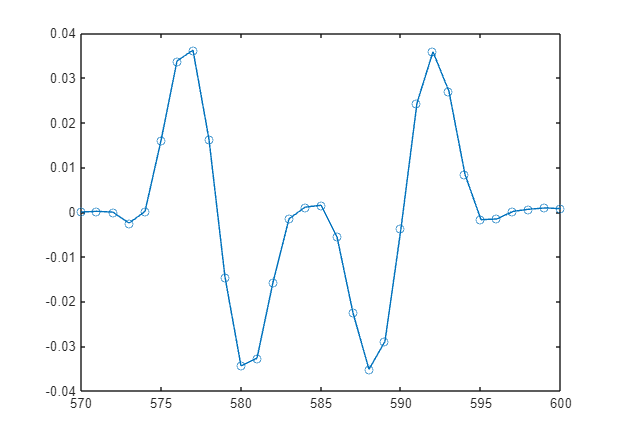

lap = imfilter(castle,fspecial("log",[],2));

p = lap(360,570:600);
plot(570:600,p,"-o");

En este ejemplo, es una imagen binaria de blancos con 1 bordes  y negros con 0 no bordes. 

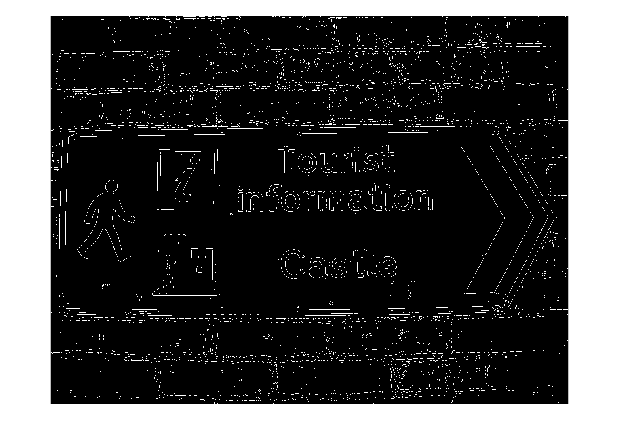

bw = edge(castle,"log");
imshow(bw);

### 11.5.2 Template Matching

En esta sección se intenta buscar patrones de diversas maneras utilizando métricas. 

SAD, SSD y NCC miden la similitud entre la imágen 1 y imágen 2.

Utilizando la imagen de la monalisa igual que en anterior ejercicio y luego se extrae un  rango. 

mona = im2double(rgb2gray(imread("monalisa.png")));
A = mona(170:220,245:295);

sad = @(I1,I2)(sum(abs(I1(:)-I2(:))));
ssd = @(I1,I2)(sum((I1(:)-I2(:)).^2));
ncc = @(I1,I2)(dot(I1(:),I2(:))/ ...
  sqrt(sum(I1(:).^2)*sum((I2(:)).^2)));
B = A;


Sum of Absolute Differences

sad(A,B)

ans = 0

Sum of Squared Differences

ssd(A,B)

ans = 0

Normalized Cross-Correlation

ncc(A,B)

ans = 1

Comparación de imágenes

1. Comparación entre B y A 

B = 0.9*A;
sad(A,B)

ans = 111.1110

2.   Imagen escalada

ssd(A,B)

ans = 5.6462

3. Imagen con desplazamiento constante

B = A+0.1;
sad(A,B)

ans = 260.1000

ssd(A,B)

ans = 26.0100

ncc(A,B)

ans = 0.9974

Mediante de este código promediar se puede comparar imágenes eliminando el sesgo de brillo, see pueden evaluar utilizando diferentes métricas frente a  ajustes en la iluminación.

submean = @(I)(I-mean(I(:)));
zsad = @(I1,I2)(sad(submean(I1),submean(I2)));
zssd = @(I1,I2)(ssd(submean(I1),submean(I2)));
zncc = @(I1,I2)(ncc(submean(I1),submean(I2)));
zsad(A,B)

ans = 2.4605e-13

zssd(A,B)

ans = 2.4884e-29

zncc(A,B)

ans = 1.0000

B = 0.9*A + 0.1;
zncc(A,B)

ans = 1.0000

Es este otro ejemplo, se va a cargar  imlaágen de ¿Donde está Wally?

- `crowd`: Imagen grande que contiene a Wally.

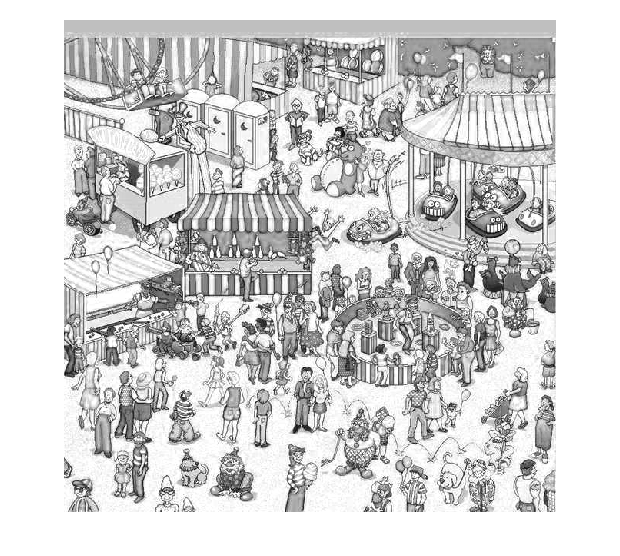

crowd = imread("wheres-wally.png");
imshow(crowd)

`Se carga la imágen de Wally`

- `wally`: Plantilla con la imagen de Wally

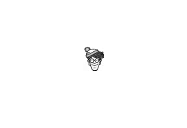

wally = imread("wally.png");
imshow(wally);

Nota del libro: la cabeza tenga aproximadamente el mismo ancho que otras cabezas en la escena de la multitud.

Mediante función normxcorr "ZNCC" normalización de la correlación la imagen para detectar áreas similare mediante entre la plantilla de "Wally" y la imágen de "crowd". Este analisis de correlaciónmustra la similitud entre ambas donde los valores más altos son los que indican las concidencias. Ahora se muestra  S junto con la barra de colores para visualizarlo.

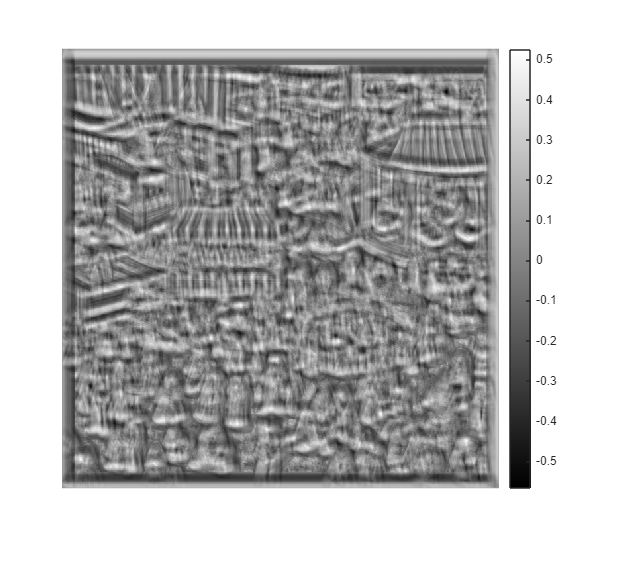

S = normxcorr2(wally,crowd);
imshow(S,[]), colorbar

En el siguiente código se generará una Imagen de similitud S utilizando la detección de picos utiliza `vision` para detectar los cinco mejores candidatos de Wally, los cuales se pueden ver marcados y se muestra el detalle de sus puntuaciones de similitud. 

Utilizando la función de  visión "`LocalMaximaFinder" mediante un mapa se podrán `detectar ubicaciones con máxima similitud. 

- 5 picos más altos

- vecindad 3x3 alrededor de cada máximo 

- picos detectados deben ser mayores que este umbral definido por la plantilla de S de "Wally"

peakFinder = vision.LocalMaximaFinder(MaximumNumLocalMaxima=5, ...
  NeighborhoodSize=[3 3],Threshold=min(S(:)));

Extraer las coordenadas de los 5 picos detectados

uvLoc = peakFinder.step(S);

Extracción de los valores de indices líneales de S  de la similitud de los picos. 

vals = S(sub2ind(size(S),uvLoc(:,2),uvLoc(:,1)))'

vals =     0.5258    0.5230    0.5222    0.5032    0.5023


Se crean las etiquetas para los valores de picos de similitud

Se agregan otras anotaciones circulares y etiquetas alrededor de los picos `S`

`Se ajustas otros de talles del texto para visualizarlos`

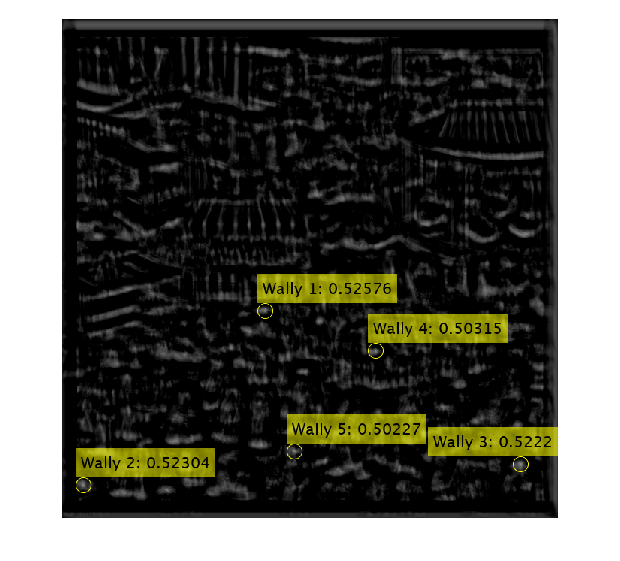

labels = "Wally " + string(1:5) + ": " + string(vals);
markedSim = insertObjectAnnotation(S,"circle",[uvLoc, ...
  10*ones(5,1)],labels,FontSize=21);
imshow(markedSim)

### 11.5.3 Nonlinear Operations

En esta sección, se utiliza la imágen de la monalisa para realizar operaciones no lineales dentro de la ventada de la imágen.

Utilizando inlfilter como una función no lineal en un sistema de vecinos que calcula con una varianza de los píxeles en cada ventana `[7 7] y se `s especifican los valores del tamaño de la ventana y una función anónima que utiliza la función var.

out = nlfilter(mona,[7 7],@(x)var(x(:)));

Luego de ordenar con valores con los filtros, se puede tener un valor específico, extrayendo el **valor máximo** de una ventana de 5 5 sobre cada píxel. De esta manera es el primer píxel ordenado en la ventana.

mx = ordfilt2(mona,1,ones(5,5));

Se puede extraer el valor de la **Mediana aproximada **de una ventana de 5 5 sobre cada píxel, que se encuentra en la posición 12. 

med = ordfilt2(mona,12,ones(5,5));

Para utilziar esta función cuyo objetivo es  agregar un ruido de impulso significativo a una copia de la imagen de la Mona Lisa, se puede usar la función imnoise.  Este  ruido es conocido como ruido impulsivo o ruido de sal y pimienta.

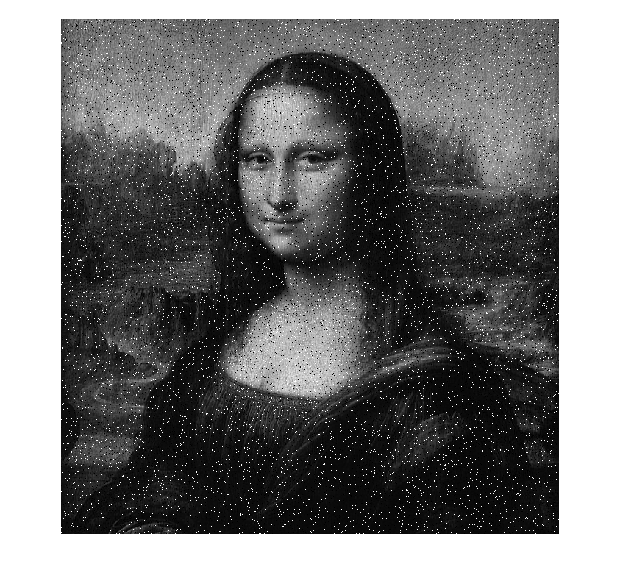

spotty = imnoise(mona,"salt & pepper");
imshow(spotty)

Para visualizar la imágen de la monalisa de otra manera nolineal, se puede aplicar un **filtro de mediana, **donde con una vecindad 3x3, se puede utilizar  el ruido creado anteriormente  para ser eliminado  y conservar los bordes. 

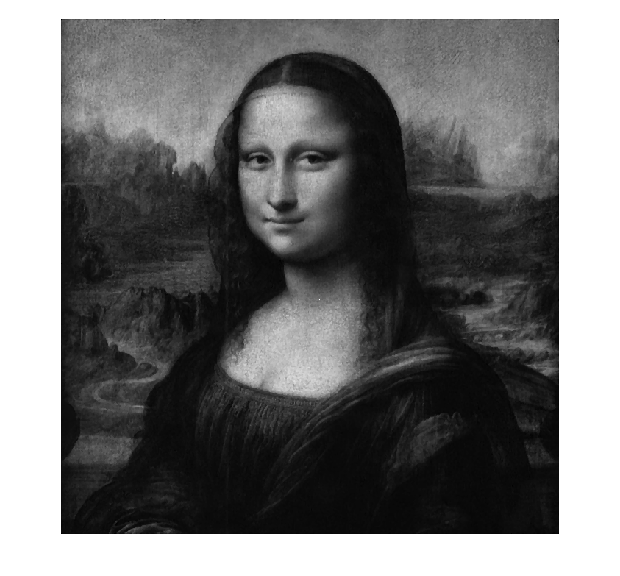

imshow(medfilt2(spotty,[3 3]))

Para crear una** máscara personalizada** para la imágen de la monalisa, se puede utilizar untercer argumento en la función de ordfilt2. 

Nota del libro: Gracias a esto, se especifica que el primer en rango máximo sobre un subconjunto de píxeles de la ventana correspondiente a los elementos distintos de cero de M.

Por lo que al final, el resultado mxn es una matriz resultado de una entrada, donde esta matriz es el máximo de los ocho vecinos de cada píxel.

M = ones(3,3);
M(2,2) = 0

M =      1     1     1
     1     0     1
     1     1     1


Ahora, habiendo realziado ese cálculo, se pueden obtener todos puntos "mínimos en vecindad" detallado en la función show donde se compara cada píxel de `mona` con el mínimo en su vecindad, dando como resultado un imagen binaria donde los píxeles más brillantes que el mínimo local aparecen como blancos y los demás como negros. 

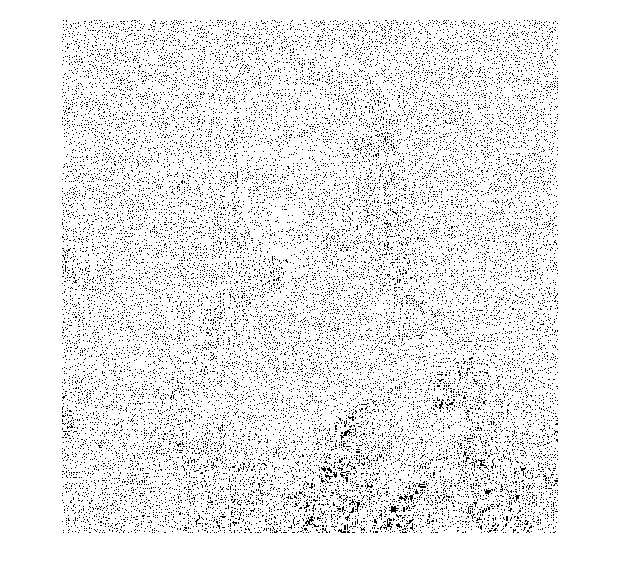

mxn = ordfilt2(mona,1,M);
imshow(mona > mxn)